# EE415 Term Project Demo Code

*by Süleyman Yasin Peker, 2305191*

clc; close all; clearvars;

Image import

load('SheppLogan.mat');
SheppLogan = SheppLogan / max(max(SheppLogan));

## I. Projection

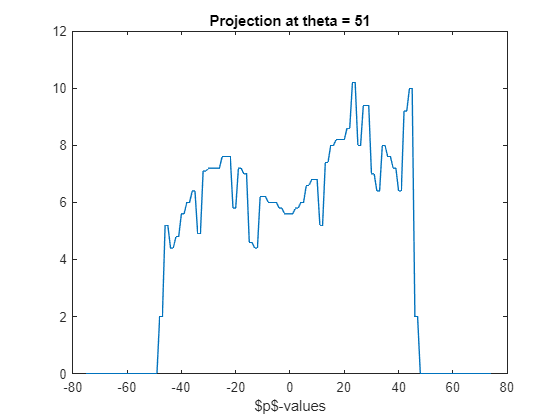

thetas = 0:179;
BeamNumber = 150;

[projections, M, myImg] = projection("SheppLogan.mat", BeamNumber, 1.8, 0);
projections = projections';
if mod(BeamNumber,2) == 0
    p_vals = -floor((BeamNumber)/2) : floor((BeamNumber)/2) - 1;
else
    p_vals = -floor((BeamNumber-1)/2) : floor((BeamNumber-1)/2);
end

p_vals = p_vals';
showAngle = 51;
figure
plot(p_vals, projections(:, showAngle))
title(['Projection at theta = ' num2str(showAngle)])
xlabel('$p$-values')

## II. Backprojections

### II.A. Without filtering

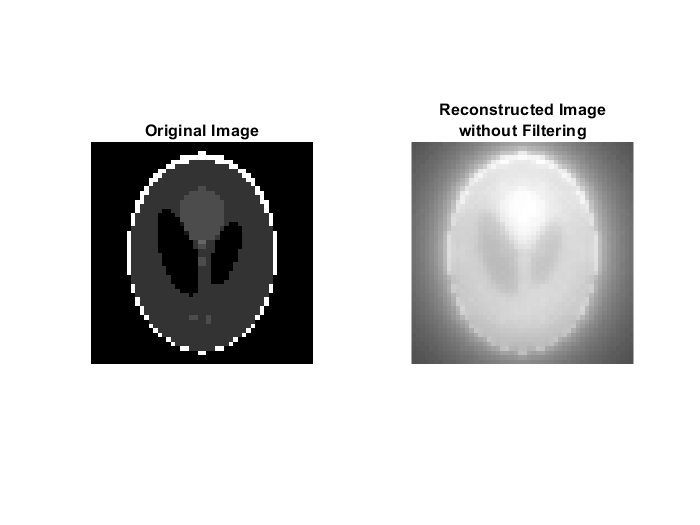

[~, square_recons_0_nofilter] = backprojection(projections',M,myImg,"triang");
square_recons_0_nofilter = square_recons_0_nofilter / max(max(square_recons_0_nofilter));

figure
tiledlayout(1, 2)
nexttile
imshow(SheppLogan)
title('Original Image')
nexttile
imshow(square_recons_0_nofilter)
title({'Reconstructed Image', 'without Filtering'})

MSE_0_nofilter = sum(sum((SheppLogan - square_recons_0_nofilter).^2)) / numel(SheppLogan)

MSE_0_nofilter = 0.3390

### II.B. With filtering, rectangular window

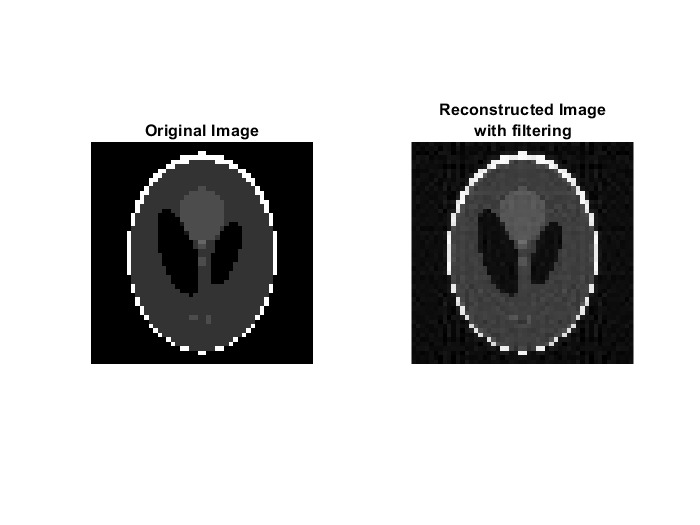

[square_recons_1_filterNoWindow] = backprojection(projections',M,myImg,"triang");   
square_recons_1_filterNoWindow = square_recons_1_filterNoWindow / max(max(square_recons_1_filterNoWindow));

figure
tiledlayout(1, 2)
nexttile
imshow(SheppLogan)
title('Original Image')
nexttile
imshow(square_recons_1_filterNoWindow)
title({'Reconstructed Image', 'with filtering'})

MSE_1_filterNoWindow = sum(sum((SheppLogan - square_recons_1_filterNoWindow).^2)) / numel(SheppLogan)

MSE_1_filterNoWindow = 0.0033

### II.C. With filtering, Cosine window

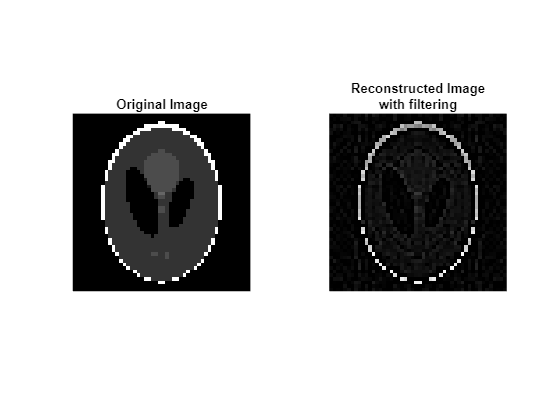

[square_recons_2_filterCosine, square_recons_0_nofilter] = backprojection(projections',M,myImg,"hamming");
square_recons_2_filterCosine = square_recons_2_filterCosine / max(max(square_recons_2_filterCosine));

figure
tiledlayout(1, 2)
nexttile
imshow(SheppLogan)
title('Original Image')
nexttile
imshow(square_recons_2_filterCosine)
title({'Reconstructed Image', 'with filtering'})

MSE_2_filterCosine = sum(sum((SheppLogan - square_recons_2_filterCosine).^2)) / numel(SheppLogan)

MSE_2_filterCosine = 0.0207